Board initialization

lungime = 15;
latime = 10;
xBoard = 3;
yBoard = 3;
xCentru = 5;
yCentru = 5;
raza = 0.8;
diametru = 2*raza;
speed = 1;
upBound = latime + yBoard;
rightBound = lungime + xBoard;
xLimita = xBoard - 3;
yLimita = 4 + lungime + xBoard;
callstr = 'set(gcbf, ''Userdata'', double(get(gcbf, ''Currentcharacter''))) ; uiresume ';
board = figure("Name","Board",'NumberTitle','off','KeyPressFcn',callstr,'userdata', 'timeout');

nrOfDivisions = 5;
spacingLungime = (lungime + 2*raza) / nrOfDivisions;
spacingLatime = (latime + 2*raza) / nrOfDivisions;
xFreq = zeros(1,nrOfDivisions);                             % xFreq tine minte de cate ori loveste mingea un anumit segment
yFreq = zeros(1,nrOfDivisions);


Key input initialization

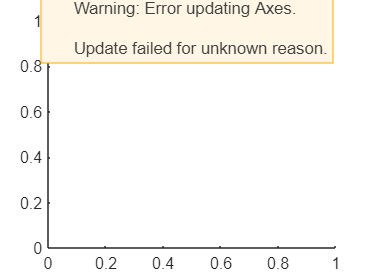

hold on;

offset = 4*raza/5;
unghi=0;
precision = 5;
str = {'cyan','green', 'blue', 'red', 'magenta','yellow'};
colorIndex = 1;
culoare = string(str);


Board setup

hold on;
grid on;
xlim([xLimita, yLimita]);
ylim([xLimita, yLimita]);
rectangle('Position',[xBoard-raza, yBoard-raza, lungime+2*raza,latime+2*raza], "LineWidth",3);
rectangle('Position',[xCentru-raza, yCentru-raza, diametru, diametru],'Curvature',[1,1], "LineWidth",1,"FaceColor",culoare(1),'EdgeColor',culoare(1));
axis square;

pt liniile care delimitează secțiuniile laturilor:

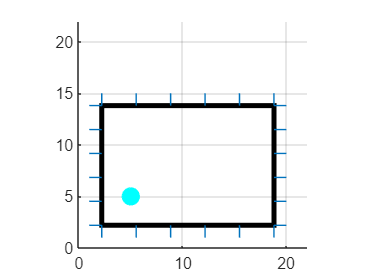

 for i=xBoard-raza:spacingLungime:rightBound+raza
     line([i,i],[yBoard-raza,yBoard-2]);
     line([i,i],[upBound+raza,upBound + 2])
 end
 for i=yBoard-raza:spacingLatime:upBound+raza
     line([rightBound+raza,rightBound+2],[i,i]);
     line([xBoard-raza,xBoard-2],[i,i]);
 end

Getting input from keyboard

uiwait;

Error using matlab.internal.editor.FigureManager.processPendingDrawnow
Error while evaluating HTMLCanvas ErrorCallback.



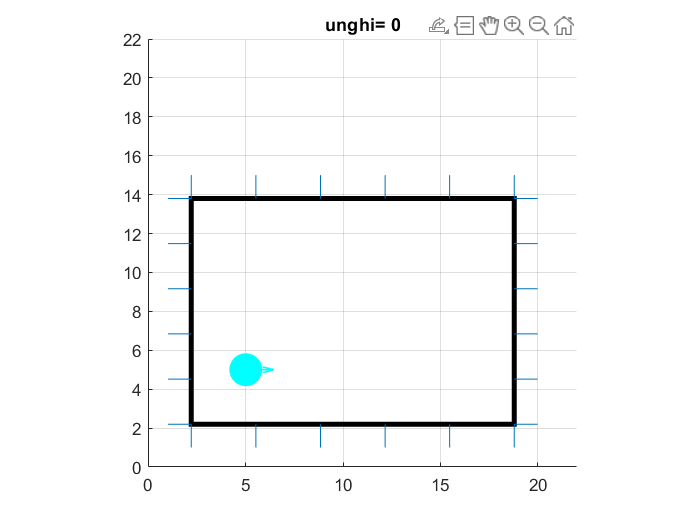

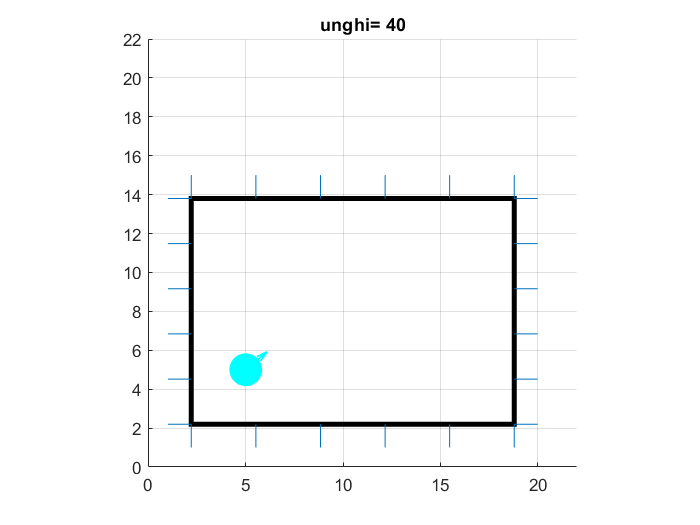

tasta = get(board,'Userdata');

if tasta == 28                      %daca apesi pe diferite sageti, incepi cu alt unghi initial
    unghi = 180;
elseif tasta == 30
    unghi = 90;
elseif tasta == 31
    unghi = 270;
end

if tasta ~= 0
    while tasta~=13
    
        hold on;

        if unghi > 360
            unghi = 0 + precision;
        elseif unghi < 0
            unghi = 360 - precision;
        end

        title("unghi= " + unghi);

        xlim([xLimita, yLimita]);
        ylim([xLimita, yLimita]);
        rectangle('Position',[xBoard-raza, yBoard-raza, lungime+2*raza,latime+2*raza], "LineWidth",3);
        sageata(xCentru,yCentru,raza+offset,unghi,culoare(colorIndex),"-",1,0)
        rectangle('Position',[xCentru-raza, yCentru-raza, diametru, diametru],'Curvature',[1,1], "LineWidth",1,"FaceColor",culoare(1),'EdgeColor',culoare(1));
        axis square; 
         for i=xBoard-raza:spacingLungime:rightBound+raza
             line([i,i],[yBoard-raza,yBoard-2]);
             line([i,i],[upBound+raza,upBound + 2])
         end
         for i=yBoard-raza:spacingLatime:upBound+raza
             line([rightBound+raza,rightBound+2],[i,i]);
             line([xBoard-raza,xBoard-2],[i,i]);
         end
                
        grid on;
                
         uiwait ;
        if isvalid(board)
            tasta = get(board,'Userdata');   % the key itself
        else
            delete(board);
            break;
        end
    
        if tasta == 28
            unghi = unghi+precision;
            clf;
        elseif tasta == 29
                unghi = unghi-precision;
                clf;
        end
        
        if colorIndex == 6
            colorIndex = 1;
        else
            colorIndex = colorIndex + 1;
        end
 

    end
end

Loop-ul

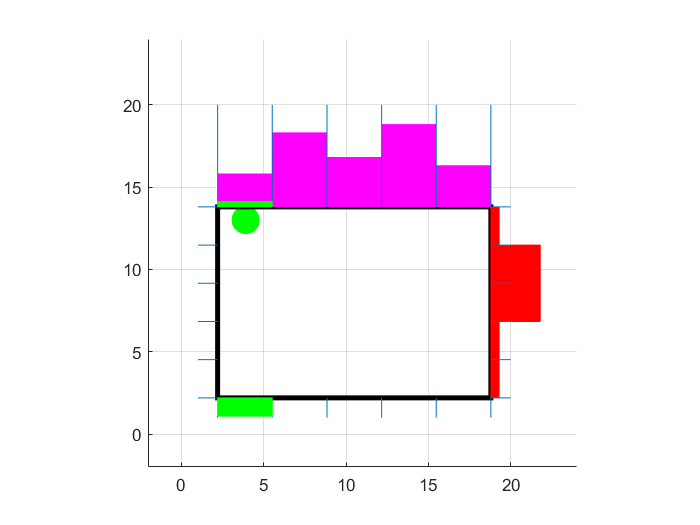

nrOfBouncings = 50;
colorIndex = 1;

xAux = xCentru - xBoard;     % -xBoard ca sa se anuleze in formula pt primu pas, ca altfel incepe decalat
yAux = yCentru - yBoard; 

ok = 1;
while nrOfBouncings

pause(0.01);
clf;
ratio = 0;

xAux = xAux + speed*cos(deg2rad(unghi));
yAux = yAux + speed*sin(deg2rad(unghi));

    if sign(lungime - mod(xAux,2*lungime)) == sign(lungime - mod(xAux+speed*cos(deg2rad(unghi)),2*lungime))%ma uit in viitor sa vad daca imi schimb directia,ca sa fac lovirea in margine sa fie exacta
        xCentru = xBoard + abs(2*lungime * mod(mod(2+sign(lungime - mod(xAux,2*lungime)),3),2) - mod(xAux,2*lungime));
    else
        if rightBound - xCentru > xCentru - xBoard        % de care latura e mai aproape, cu aia devine egala
            xCentru = xBoard;
        else
            xCentru = rightBound;
        end
    end

    if sign(latime - mod(yAux,2*latime)) == sign(latime - mod(yAux+speed*sin(deg2rad(unghi)),2*latime))
        yCentru = yBoard + abs(2*latime * mod(mod(2+sign(latime - mod(yAux,2*latime)),3),2) - mod(yAux,2*latime));
    else
        if upBound - yCentru > yCentru - yBoard
            yCentru = yBoard;
        else
            yCentru = upBound;
        end
    end

grid on;
hold on;
if max(xFreq) > max(yFreq)
    maxim = max(xFreq);
else 
    maxim = max(yFreq);
end

xlim([xLimita - floor(maxim/5), yLimita + floor(maxim/5)]);   %se schimba dimensiunea graficului pe masura ce creste inaltimea segmentelor lovite 
ylim([xLimita - floor(maxim/5), yLimita + floor(maxim/5)]);

rectangle('Position',[xCentru-raza, yCentru-raza, diametru, diametru],'Curvature',[1,1], "LineWidth",1,"FaceColor",culoare(colorIndex),'EdgeColor',culoare(colorIndex));
rectangle('Position',[xBoard-raza, yBoard-raza, lungime+2*raza,latime+2*raza], "LineWidth",3);
%  plot(xCentru,yCentru,"x",'Color','black');

 k=1;
 for i=xBoard-raza:spacingLungime:rightBound+raza       %afisarea unor dreptunghiuri deasupra mesei care indica de cate ori a fost lovit una numit segment
     if i < rightBound+raza                             %pt ca altfel face un patrat in plus in afara mesei
        rectangle('Position',[i, upBound+raza, spacingLungime,0.5*xFreq(min(k,nrOfDivisions))], "FaceColor","magenta", "EdgeColor","magenta");
     end
     k = k+1;
     line([i,i],[yBoard-raza,yBoard-2]);
     line([i,i],[upBound+raza,upBound + 2 + max(xFreq)*0.5]); 
 end

 k=1;

 for i=yBoard-raza:spacingLatime:upBound+raza
     if i < upBound+raza                             %pt ca altfel face un patrat in plus in afara mesei
        rectangle('Position',[xBoard + lungime + raza, i, 0.5*yFreq(min(k,nrOfDivisions)), spacingLatime], "FaceColor","red", "EdgeColor","red");
     end
     k = k+1;
     line([rightBound+raza,rightBound+2],[i,i]);
     line([xBoard-raza,xBoard-2],[i,i]);
 end


%  line([5, xCentru],[5,yCentru]);
axis square;

    if  xCentru == rightBound || xCentru == xBoard || yCentru == yBoard || yCentru == upBound     %daca ating o margine
        while true
            r = normrnd(0,5);
            if r < 5 && r > -5
                break;
            end
        end
          unghi = unghi + r; 
           colorIndex = abs(round(r)) + 1;
    
          if yCentru == yBoard || yCentru == upBound
              ratio = floor((xCentru-xBoard+raza)/spacingLungime) ;       %determin in care segment ma aflu cand am lovit marginea

              xFreq(ratio+1) = xFreq(ratio+1) + 1;

              rectangle('Position',[xBoard + spacingLungime*(ratio) - raza, yBoard-raza-spacingLungime/3, spacingLungime,spacingLungime/3], "FaceColor","green", "EdgeColor","green");
              rectangle('Position',[xBoard + spacingLungime*(ratio) - raza, upBound+raza, spacingLungime,spacingLungime/10], "FaceColor","green", "EdgeColor","green"); 
%               pause(1);                             %niste dreptunghiuri pt efect vizual cand mingea loveste marginea      
          else
              ratio = floor((yCentru-yBoard+raza)/spacingLatime) ;

              yFreq(ratio+1) = yFreq(ratio+1) + 1;

              rectangle('Position',[ xBoard + lungime + raza, yBoard + (spacingLatime)*(ratio) - raza, 0.5, spacingLatime], "FaceColor","yellow", "EdgeColor","yellow");
              rectangle('Position',[ xBoard - raza - 0.5, yBoard + (spacingLatime)*(ratio) - raza, 0.5, spacingLatime], "FaceColor","yellow", "EdgeColor","yellow");
                
%               pause(1);

          end
        
          nrOfBouncings = nrOfBouncings - 1;
     
    end

end

Histograma

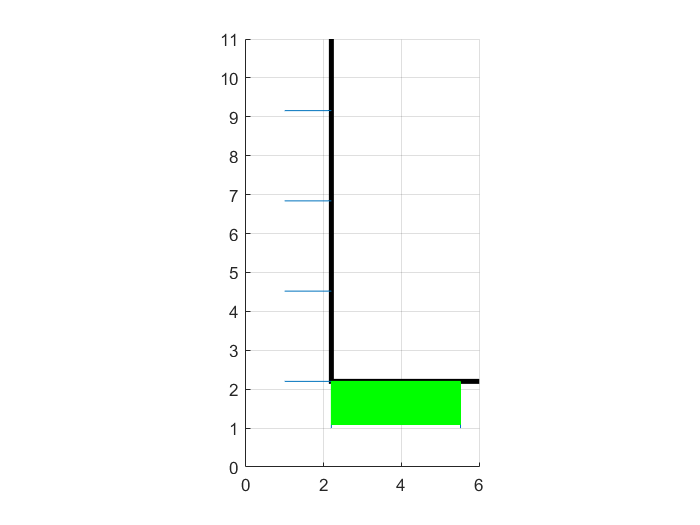

nr = 0;

for i=1:length(xFreq)
    nr = nr + xFreq(i);
end
k=1;

x = zeros(1,nr);

for i=1:nrOfDivisions
    for j=1:xFreq(i)
        x(k) = i;
        k = k+1;
    end
end


y2 = zeros(1,nr); %pt y-ul din afisarea histogramei
nr = 0;

for i=1:length(yFreq)
    nr = nr + yFreq(i);
end
k=1;

y = zeros(1,nr);

for i=1:nrOfDivisions
    for j=1:yFreq(i)
        y(k) = i;
        k = k+1;
    end
end

hold off;
% histogram(y)
hold on;
grid on;
axis square;
axis equal;
xlim([0,nrOfDivisions+1]);
ylim([0,max(xFreq)+1]);


hold off;

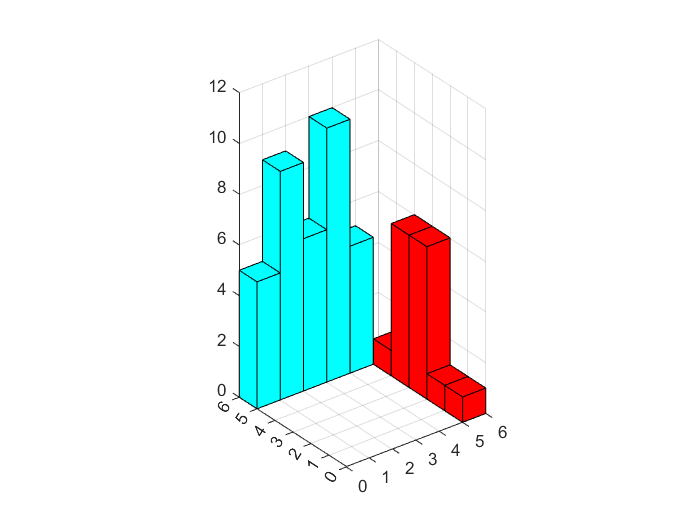

hist3([x.'-1,y2.' + nrOfDivisions - 0.5],"Ctrs", {0.5:1:nrOfDivisions, nrOfDivisions+0.5:1:nrOfDivisions+1.5} , "FaceColor", "cyan");

hold on;
grid on;
% y = y-(nrOfDivisions+2);
y3 = zeros(1,nr) + nrOfDivisions;
hist3([y3.'+ 0.5, y.' - 1], "Ctrs", {nrOfDivisions+0.5:1:nrOfDivisions+1.5, 0.5:1:nrOfDivisions}, "FaceColor", "red");
axis square;
axis equal;
xticks(0:1:nrOfDivisions+1);
yticks(0:1:nrOfDivisions+1);
% xlim([0,nrOfDivisions+1]);
% ylim([0,max(xFreq)+1]);
xlim([0, nrOfDivisions+1])
ylim([0, nrOfDivisions+1])
zlim([0, maxim+2])